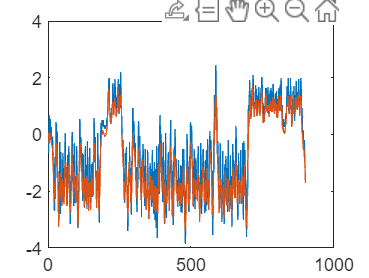

clc,clear
%initialize parameter
m1=4866;                    %浮子质量 (kg)
r_f=1;                      %浮子底半径 (m)
h_cast=3;                   %浮子圆柱部分高度 (m)
h_cone=0.8;                 %浮子圆锥部分高度 (m)
m_cast=m1*90/98;            %圆柱质量 (kg)
V_cast=pi*r_f^2*h_cast;     %圆柱体积 (m3)
m_cone=m1*8/90;             %圆锥质量 (kg)
V_cone=1/3*h_cone*pi*r_f^2; %圆锥体积(m3)
V_max=V_cone+V_cast;        %浮子体积
m2=2433;                    %振子质量 (kg)
r_v=0.5;                    %振子半径 (m)
m_add=1335.535;             %垂荡附加质量 (kg)
g=9.8;                      %重力加速度 (m/s2)
G1=m1*g;                    %浮子重力  (N)
G2=m2*g;                    %振子重力  (N)
rho=1025;                   %海水的密度 (kg/m3)
ke=80000;                   %弹簧刚度 (N/m)
l0=0.5;                     %弹簧原长 (m)
w=1.4005;                   %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）
T=2*pi/w;                   %波浪周期（s)                   
kr=656.3616;                %垂荡兴波阻尼系数 (N·s/m)
k=10000;                    %阻尼系数
f_max=6250;                 %垂荡激励力振幅 (N)
dt=0.2;                     %步长设为0.1s
T_end=40*T;                 %总数值模拟时间(s)        
iter_times=ceil(T_end/dt);  %总迭代次数 
l=zeros(iter_times,1);
l(1)=l0-m2*g/ke;            %弹簧的初始长度 (m)
v1=l;
v1(1)=0;                    %浮子的初始速度 (m/s)
v2=l;
v2(1)=0;                    %振子的初始速度 (m/s)
x_f=l;
x_f(1)=0;                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
x_v=l;  
L=2.3-2/15;                 %重心距底端距离
x_v(1)=-(L-0.8-l0)+0.25;         %振子的初始位移 (m)
h=3.8-L-1;                  %水面的高度(m)
V0=V_max-pi*r_f^2*(3.8-L-h);%初始沉入水中体积(m3)
delta_x=l;
delta_x(1)=l0;
for i=1:iter_times+1
     t=(i-1)*dt;
    v1(i+1)=v1(i)+dt*(G1-sgn(v1(i))*ca_f_r(k,v1(i),v2(i))-kr*v1(i) ...
        -sgn(l(i)-l0)*ca_f_e(ke,l(i),l0)+f_max*cos(w*t) ...
        -ca_f_float(rho,g,x_f(i),L,V0,V_max,r_f,h))/(m1+m_add);%or -f*cos(wt)
    v2(i+1)=v2(i)+dt*(G2-sgn(v2(i))*ca_f_r(k,v1(i),v2(i)) ...
        +sgn(l(i)-l0)*ca_f_e(ke,l(i),l0))/m2;
    x_f(i+1)=x_f(i)+(v1(i)+v1(i+1))/2*dt;
    x_v(i+1)=x_v(i)+(v2(i)+v2(i+1))/2*dt;
    l(i+1)=l0+x_f(i+1)-x_v(i+1);
    delta_x(i+1)=(v1(i+1)-v2(i+1))*dt;
   
    % [f1,f2,x_f(i+1),x_v(i+1),l(i+1)]=ca_f1_f2(v1(i),v2(i),x_f(i),x_v(i),l(i),t,dt);
    % K1=f1;
    % Kp1=f2;
    % [f1,f2,x_f(i+1),x_v(i+1),l(i+1)]=ca_f1_f2(v1(i)+dt/2*K1,v2(i)+dt/2*Kp1,x_f(i+1),x_v(i+1),l(i+1),t+dt/2,dt);
    % K2=f1;
    % Kp2=f2;
    % [f1,f2,x_f(i+1),x_v(i+1),l(i+1)]=ca_f1_f2(v1(i)+dt/2*K2,v2(i)+dt/2*Kp2,x_f(i+1),x_v(i+1),l(i+1),t+dt/2,dt);
    % K3=f1;
    % Kp3=f2;
    % [f1,f2,~,~,~]=ca_f1_f2(v1(i)+dt/2*K3,v2(i)+dt/2*Kp3,x_f(i+1),x_v(i+1),l(i+1),t+dt,dt);
    % K4=f1;
    % Kp4=f2;
    % v1(i+1)=v1(i)+dt/6*(K1+2*K2+2*K3+K4);
    % v2(i+1)=v2(i)+dt/6*(Kp1+2*Kp2+2*Kp3+Kp4);
    % x_f(i+1)=x_f(i)+(v1(i)+v1(i+1))/2*dt;
    % x_v(i+1)=x_v(i)+(v2(i)+v2(i+1))/2*dt;
    % l(i+1)=l(i)+(v1(i+1)-v2(i+1))*dt;
    % delta_x(i+1)=(v1(i+1)-v2(i+1))*dt;
end
plot(x_v)
hold on
plot(x_f)
hold off

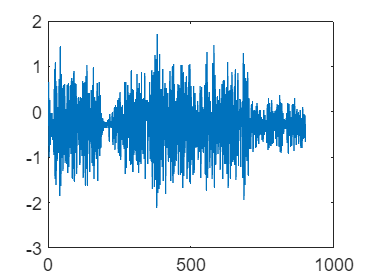

plot(l-l0)
hold off

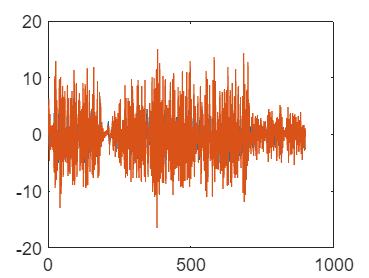

plot(v1)
hold on
plot(v2)
hold off

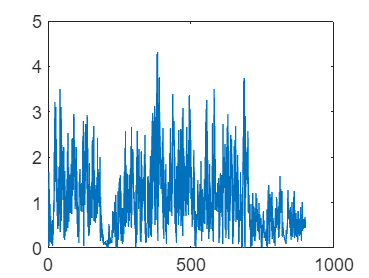

plot(abs(delta_x))

function f=ca_f_r(kr,v1,v2)
    %计算垂荡阻尼力
    f=kr*abs(v1-v2);
end
function f=ca_f_e(k,L,L0)
    %计算弹力
    f=k*abs(L-L0);
end
function f=ca_f_float(rho,g,x,L,V0,V_max,r_cost,h)
    %计算浮力   
    if x>=1
        delta_V=V_max-V0;
    elseif abs(x)<=1||abs(x)<=2
        delta_V=(-x)*pi*r_cost^2; 
    elseif x<-(h+L-0.8)&&x>-(h+L)
        r=(x+h+L)/(0.8+x+h+L)*0.8;
        delta_V=-pi*r_cost^2*(h+L-0.8)-(1/3*pi*0.8*r_cost*2-1/3*pi*r^2);
    else 
        delta_V=-V0;
    end
    f=rho*g*(V0+delta_V);
end
function y=sgn(x)
    if x>0
        y=1;
    elseif x<=0
        y=-1;
    else
        y=0;
    end
end
function [f1,f2,x_f_1,x_v_1,l_1]=ca_f1_f2(v1_0,v2_0,x_f_0,x_v_0,l_0,t,dt)                
    r_f=1;                     
    h_cast=3;                  
    h_cone=0.8;                       
    V_cast=pi*r_f^2*h_cast;          
    V_cone=1/3*h_cone*pi*r_f^2;
    V_max=V_cone+V_cast;                
    g=9.8;                                                               
    m1=4866; 
    m2=2433; 
    L=2.3-2/15; 
    m_add=1335.535;  
    g=9.8;           
    G1=m1*g;         
    G2=m2*g;         
    rho=1025;        
    ke=80000;        
    l0=0.5;          
    w=1.4005;              
    kr=656.3616;     
    f_max=6250; 
    h=3.8-L-1; 
    V0=V_max-pi*r_f^2*(3.8-L-h);
    v1_1=v1_0+dt*(G1-sgn(v1_0)*ca_f_r(kr,v1_0,v2_0) ...
       -sgn(l_0-l0)*ca_f_e(ke,l_0,l0)+f_max*cos(w*t) ...
        -ca_f_float(rho,g,x_f_0,L,V0,V_max,r_f,h))/(m1+m_add);%or -f*cos(wt
    f1=(G1-sgn(v1_0)*ca_f_r(kr,v1_0,v2_0) ...
        -sgn(l_0-l0)*ca_f_e(ke,l_0,l0)+f_max*cos(w*t) ...
        -ca_f_float(rho,g,x_f_0,L,V0,V_max,r_f,h))/(m1+m_add);
    v2_1=v2_0+dt*(G2-sgn(v2_0)*ca_f_r(kr,v1_0,v2_0) ...
       +sgn(l_0-l0)*ca_f_e(ke,l_0,l0))/m2;
    f2=(G2-sgn(v2_0)*ca_f_r(kr,v1_0,v2_0) ...
        +sgn(l_0-l0)*ca_f_e(ke,l_0,l0))/m2;
    x_f_1=x_f_0+(v1_0+v1_1)/2*dt;
    x_v_1=x_v_0+(v2_1+v2_1)/2*dt;
    l_1=l_0+(v1_1-v2_1)*dt; 
end
% function f=f1()
%         f=(G1-sgn(v1_0)*ca_f_r(kr,v1_0,v2_0) ...
%         -sgn(l_0-l0)*ca_f_e(ke,l_0,l0)+f_max*cos(w*t) ...
%         -ca_f_float(rho,g,x_f_0,L,V0,V_max,r_f,h))/(m1+m_add);
% end